# Optimizing Gemm

This Live Script helps you visualize the performance of varous implementation of matrix-matrix multiplication.

Clear all variables.

clear

On the terminal command line, type 'make test_IJP' which will compile and time the implementation in Gemm_IJP.c.  Alternatively, uncomment the below and execute:

system( 'make test_IJP' );

Makefile:88: warning: overriding commands for target `driver_JPI.x'
Makefile:64: warning: ignoring old commands for target `driver_JPI.x'
Makefile:91: warning: overriding commands for target `test_JPI'
Makefile:67: warning: ignoring old commands for target `test_JPI'
echo "your_version = 'IJP';" > output_IJP.m
echo " " >> output_IJP.m
echo "3 24 500 24" | ./driver_IJP.x >> output_IJP.m


When completed, this creates output file 'output_IJP' with timing data.  This Life Script then creates graphs from that timing data.

## Load timing data

output_IJP
data_IJP = data;
version_IJP = your_version;

## Make sure you are getting the right answer

In the output file, for each execution of your implementation, timing data is collected as well as how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of 1e-11  or smaller.  Notice that you can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data_IJP( :, 6 ) ) )

MaxAbsDiff = 3.2685e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Plot execution time.

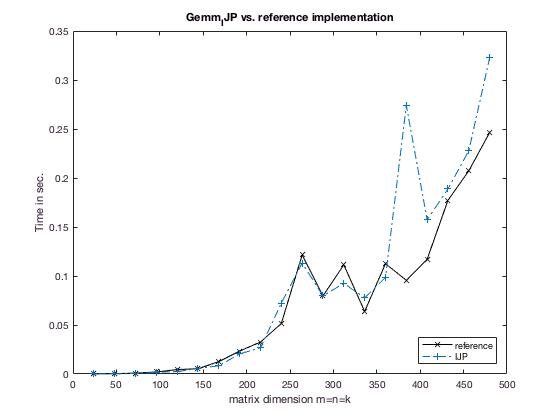

% Plot the reference implementation
plot( data_IJP( :, 1 ), data_IJP( :, 2 ), 'k-x' );   

hold all
 % Plot the performance data for Gemm_IJP
plot( data_IJP( :, 1 ), data_IJP( :, 4 ), '-.+' ); 

title( 'Gemm_IJP vs. reference implementation' );
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Time in sec.' );
legend( 'reference', ...
         version_IJP, ...
        'Location', 'SouthEast' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Plot performance in GFLOPS

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.  This performance data is already computed in the fourth column of array "data_Gemm".

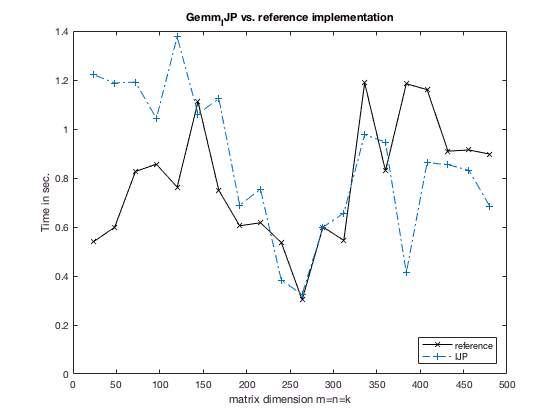

figure

% Plot the reference implementation
plot( data_IJP( :, 1 ), data_IJP( :, 3 ), 'k-x' );   

hold all
 % Plot the performance data for Gemm_IJP
plot( data_IJP( :, 1 ), data_IJP( :, 5 ), '-.+' ); 

title( 'Gemm_IJP vs. reference implementation' );
xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS' );
legend( 'reference', ...
         version_IJP, ...
        'Location', 'SouthEast' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero